NAME:- P.Sai Uttej

REG NO:- 19BCE7163

QUESTION :- Solve the BVP.


$$d^2 y\;/{\mathrm{dx}}^2 =2\frac{\mathrm{dy}}{\mathrm{dx}}-2y,y\left(0\right)=0\ldotp 1,y\left(3\right)=0\ldotp 1e^3 \mathrm{cos}\left(3\right)$$



aa=0; bb=3; n=20; h= (bb-aa) /n;
x=h:h:bb

x =     0.1500    0.3000    0.4500    0.6000    0.7500    0.9000    1.0500    1.2000    1.3500    1.5000    1.6500    1.8000    1.9500    2.1000    2.2500    2.4000    2.5500    2.7000    2.8500    3.0000



p=2*zeros(1, n-1) ; q=2*ones(1, n-1) ; r=0*x.*(x-100);
ya=0.1; yb=0.1*exp(3)*cos(3);
h2=h/2; hh=h*h;

a=zeros(1, n-1) ; a(1:n-2) =1-p(1, 1:n-2) *h2;
d = -(2+hh*q) ;

b=zeros (1, n-1) ; b(2:n-1) =1+p(1, 2:n-1)*h2;

c(1) =hh*r(1) - (1+p(1)*h2)*ya;
c(2:n-2) =hh*r(2:n-2) ;
c(n-1) =hh*r(n-1) -(1-p(n-1)*h2)*yb;

m=length (d) ; a(1) =a (1) /d(1) ; c(1)=c(1) /d(1) ;
for i=2 :m-1
    denom=d (i) -b (i) *a (i-1) ;
    if (denom==0) , error('zero in denominator' ) , end
    a (i) =a (i) /denom;
    c(i)= (c(i)-b(i) *c (i-1) ) /denom;

end
c (m) = (c (m) -b (m) *c (m-1) ) / (d(m) - b(m) *a (m-1) );
y (m) =c (m) ;
for i=m-1: -1:1
    y (i) =c(i) - a(i) *y(i+1) ;
end

xx= [aa x] ; yy=[ya y yb]

yy =     0.1000    0.0686    0.0403    0.0138   -0.0120   -0.0384   -0.0665   -0.0976   -0.1332   -0.1747   -0.2240   -0.2835   -0.3557   -0.4439   -0.5521   -0.6851   -0.8489   -1.0510   -1.3003   -1.6082   -1.9885


yy1=[yy(1:20) yb]

yy1 =     0.1000    0.0686    0.0403    0.0138   -0.0120   -0.0384   -0.0665   -0.0976   -0.1332   -0.1747   -0.2240   -0.2835   -0.3557   -0.4439   -0.5521   -0.6851   -0.8489   -1.0510   -1.3003   -1.6082   -1.9885


out= [xx' yy1']

out =          0    0.1000
    0.1500    0.0686
    0.3000    0.0403
    0.4500    0.0138
    0.6000   -0.0120
    0.7500   -0.0384
    0.9000   -0.0665
    1.0500   -0.0976
    1.2000   -0.1332
    1.3500   -0.1747


disp ( ' out' )

 out


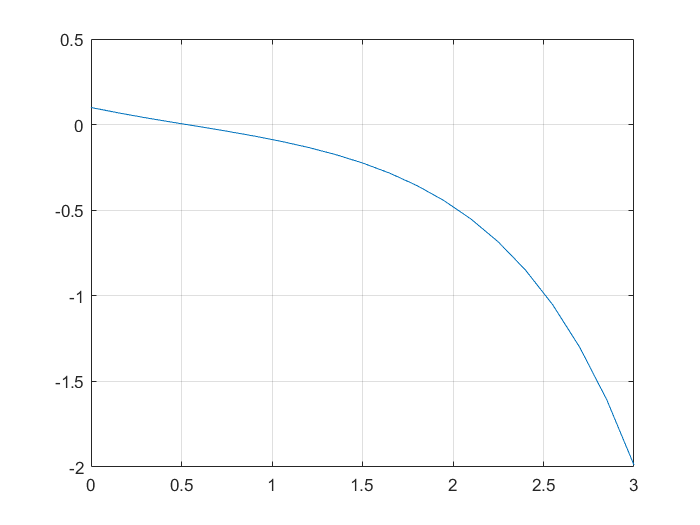

plot (xx' , yy1' )
grid on